# Metoda hlavních komponent

**Matěj Klimeš, Tomáš Zbíral**

**YGEI - ZS 2024**

**29.11.2024**

**Zadání:** S využitím oblíbeného programovacího prostředí či výpočetního sw (Python, Matlab, Excel, …) vytvořte dva  příklady dvourozměrných datových sad (např. po 20 pozorováních), na nichž ukážete význam transformace  hlavních komponent. V prvním příkladě bude po transformaci první hlavní komponenta obsahovat alespoň  70% informace datového souboru. Ve druhém případě bude vliv transformace minimální (obsah informace v  původních a transformovaných osách se nebude lišit více než o 10%). V obou případech spočítejte vlastní čísla  a vlastní vektory kovarianční matice.

### Uživatelský vstup pro volbu příkladu

clc; close all; clear; format longg
prompt = "Zadejte: 1 - příklad, kde má transformace hlavních komponent význam \n" + ...
    "         2 - příklad, kde nemá transformace hlavních komponent význam: \n" + ...
    "Odpověď: ";
priklad=input(prompt);


### Generování dat na základě uživatelského výběru

if priklad ==1
% priklad 1
mu = [2 3];
Sigma = [1 1.5; 1.5 3];
rng('default')
x = mvnrnd(mu,Sigma,100);
% pripadne nejak takto
% x(:,1) =  rand(100,1); % x bude náhodné číslo mezi 0 a 1
% x(:,2) = 2 * x + 0.1 * randn(100, 1); % y je lineárně závislé na x, ale s přidaným šumem


elseif priklad ==2
% priklad 2
mu = [2 2];
Sigma = [2 0; 0 3];
rng('default')
x = mvnrnd(mu,Sigma,100);
% pripadne nejak takto
% x(:,1) = 0.5*randn(100,1)-2;
% x(:,2) = 0.5*randn(100,1);

else
    error('Zadán chybný vstup')
end

### Zobrazení rozmístění vstupních dat

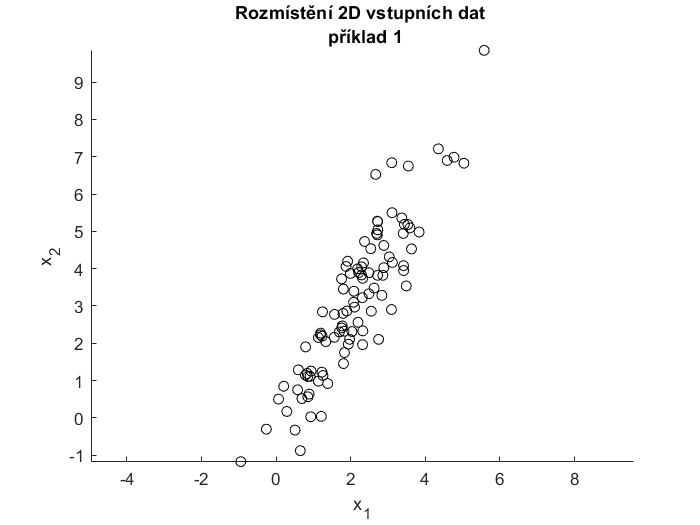

scatter(x(:,1),x(:,2), 'ok');
title(sprintf('Rozmístění 2D vstupních dat \n příklad %d', priklad));
xlabel('x_1'); ylabel('x_2');
axis equal;

### Normalizace dat

Mx=mean(x); % výpočet těžiště
X=x-Mx;     % redukce hodnot těžišti
Sd=std(x);  % směrodatné odchylky
% normalizace
Xn(:,1)=X(:,1)./Sd(1);
Xn(:,2)=X(:,2)./Sd(2);

### Kovarianční matice

- pro nenormalizovaná data

S=cov(X)

S =             1.351171255832          2.10306645977161
          2.10306645977161          4.02666028520273


- pro normalizovaná data

Sn=cov(Xn)

Sn =                          1         0.901623666151484
         0.901623666151484                         1


### Korelační matice

- pro nenormalizovaná data

R = corrcoef(X)

R =                          1         0.901623666151484
         0.901623666151484                         1


- pro normalizovaná data

Rn = corrcoef(Xn)

Rn =                          1         0.901623666151484
         0.901623666151484                         1


### Vlastní čísla kovarianční matice

[V,D] = eig(S);
[d,ind] = sort(diag(D),'descend');
Ds = D(ind,ind)

Ds =           5.18139423999049                         0
                         0         0.196437301044247


### Vlastní vektory kovarianční matice (hlavní komponenty)

Vs = V(:,ind)

Vs =          0.481293794966528        -0.876559343642356
         0.876559343642356         0.481293794966528


### Zobrazení původních dat a směrů hlavních komponent

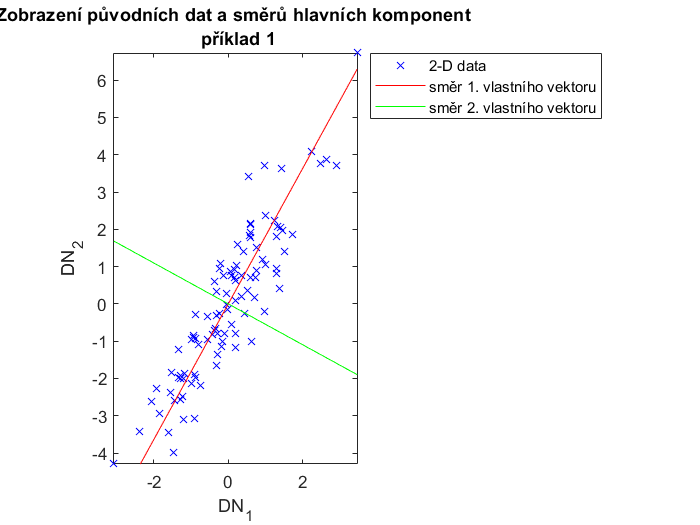

pc=Vs;
figure
plot(X(:,1), X(:,2), 'bx')
axis equal;
hold on;
line([min(X(:,1)),max(X(:,1))], [min(X(:,1))*pc(2,1)/pc(1,1),max(X(:,1))*pc(2,1)/pc(1,1)], 'Color', [1 0 0]);
hold on;
line([min(X(:,1)),max(X(:,1))], [min(X(:,1))*pc(2,2)/pc(1,2),max(X(:,1))*pc(2,2)/pc(1,2)], 'Color', [0 1 0]);
legend('2-D data','směr 1. vlastního vektoru','směr 2. vlastního vektoru',Location='bestoutside');
xlabel('DN_1'); ylabel('DN_2');
title(sprintf('Zobrazení původních dat a směrů hlavních komponent \n příklad %d', priklad))
hold off
axis([min(X(:,1)) max(X(:,1)) min(X(:,2)),max(X(:,2))])

### Transformace dat do směru hlavních komponent

X_rot = X*pc;

### Zobrazení dat v osách hlavních komponent

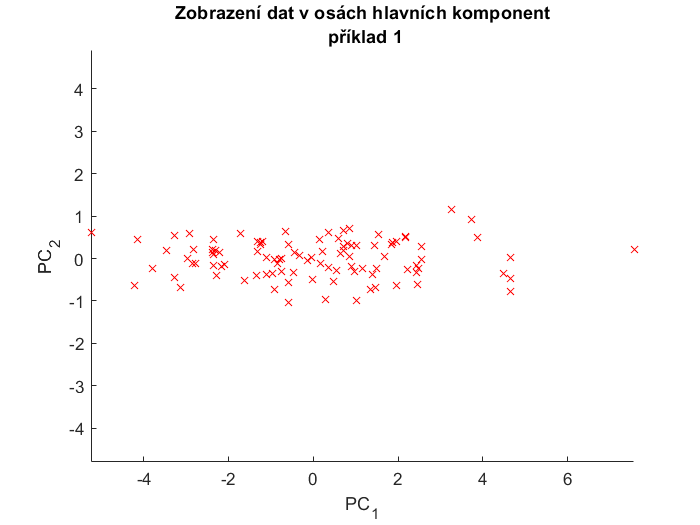

figure;
scatter(X_rot(:,1), X_rot(:,2), 'rx');
title(sprintf('Zobrazení dat v osách hlavních komponent\n příklad %d', priklad));
xlabel('PC_1'); ylabel('PC_2');
axis equal;

### Informační obsah první komponenty

inf1 = d(1)/sum(d)

inf1 =          0.963472767872076


### Informační obsah druhé komponenty

inf2 = d(2)/sum(d)

inf2 =          0.036527232127924
